## Import Data

clear all;
clc;
data = readtable("BuckPIDStep10to60.csv");
data = fillmissing(data,'nearest')

data = 2002×3 table
      Var1        Var2      Var3  
    _________    ______    _______

     -9.6e-05         2          3
     -9.6e-05         2          3
     -9.6e-05    4.9345    0.72902
    -9.55e-05    4.9345    0.72902
     -9.5e-05    4.9345    0.72902
    -9.45e-05    4.9196    0.74014
     -9.4e-05    4.9284    0.74317
    -9.35e-05     4.928    0.74636
     -9.3e-05    4.9246    0.74388
    -9.25e-05    4.9355    0.74509
     -9.2e-05    4.9262    0.74603
    -9.15e-05    4.9298    0.74247
     -9.1e-05    4.9367    0.74432
    -9.05e-05    4.9383    0.74344
       -9e-05    4.9304    0.73931
    -8.95e-05    4.9302    0.73847


data([1,2],:) = [];
% Step info
step_bot=10;
step_top=60;

## Assign Variables

% Seperate values
t = table2array(data(:,1))+9.6e-5;
ADC = round(table2array(data(:,3))/5*1024)

ADC =    149
   149
   149
   152
   152
   153
   152
   153
   153
   152


OCR = table2array(data(:,2));
% Match to duty cycle
OCR = 60-round(OCR/5)*50

OCR =     10
    10
    10
    10
    10
    10
    10
    10
    10
    10



% Find index before step
idx = find(OCR<60,1,'last')

idx = 192


% Trim data with new index
t = t(idx-5:end);
ADC = ADC(idx-5:end);
OCR = OCR(idx-5:end);

% Reset time and find sampling time
t = t-t(1);
T_s=t(2)-t(1)

T_s = 5.0000e-07

## Plot Real Data

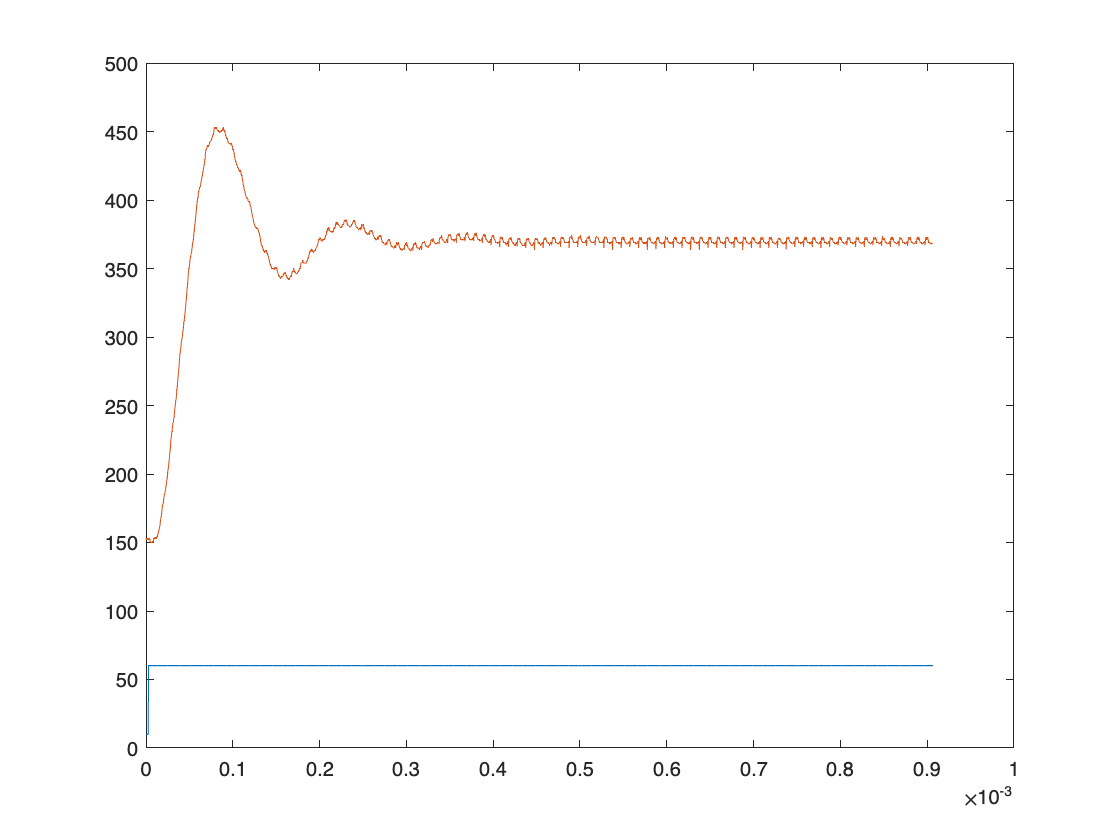

clf;
plot(t,OCR)
hold on
plot(t,ADC)
hold off

clf

## Identify Transfer Functions

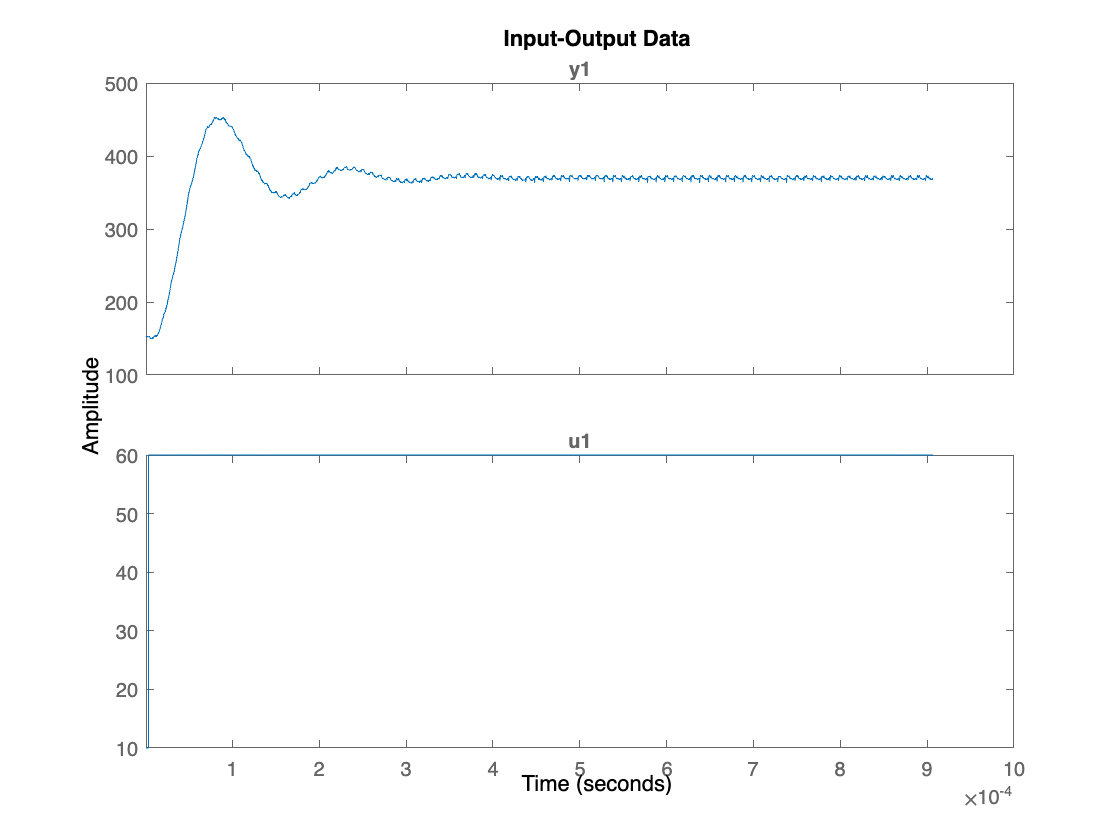

idd = iddata(ADC,OCR,T_s);
plot(idd)

G=tfest(idd,2,0)

G =
 
  From input "u1" to output "y1":
           1.386e10
  ---------------------------
  s^2 + 3.052e04 s + 2.242e09
 
Continuous-time identified transfer function.

Parameterization:
   Number of poles: 2   Number of zeros: 0
   Number of free coefficients: 3
   Use "tfdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                         
Estimated using TFEST on time domain data "idd".
Fit to estimation data: 88.34%                  
FPE: 24.4, MSE: 24.27                           


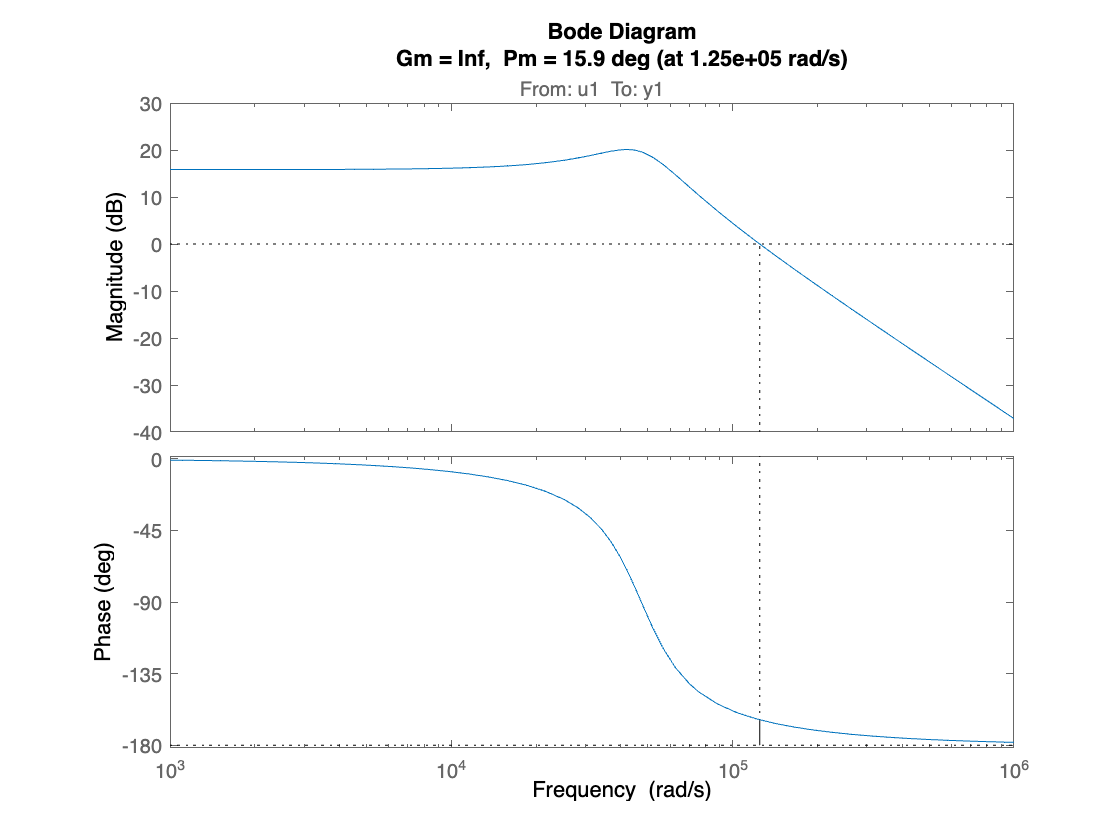

margin(G)

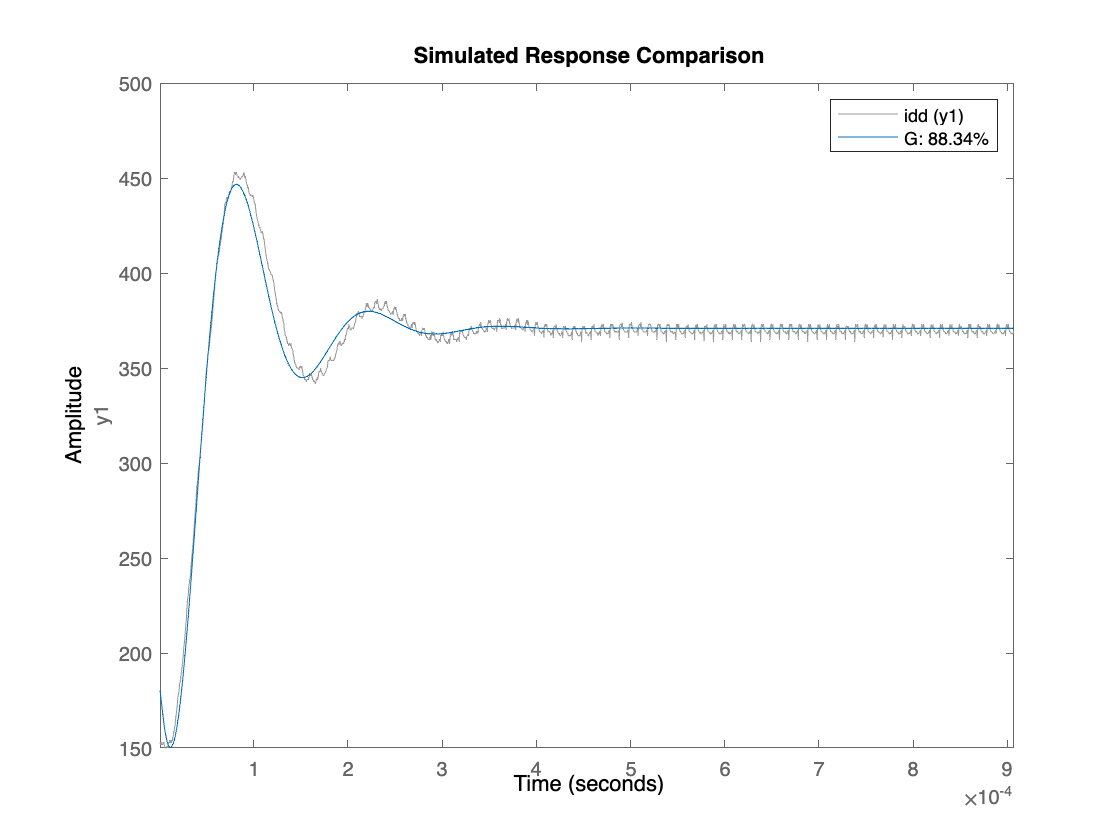

compare(idd,G)

## Create PID Controller

format long
abs(pole(G))

ans = 1.0e+04 *

   4.734637643390539
   4.734637643390539


gm = 60; Ni=5; alpha=0.2;
[wc, Kp, taui,taud, ok] = findpid(G, gm, Ni,alpha)

ans = 'Found 1 valid solution(s) out of 1 phase crossing(s)'

wc =      8.234991884607676e+04


Kp =    0.164193178817579


taui =      6.071651399372575e-05


taud =      2.715325052935761e-05


ok =      1


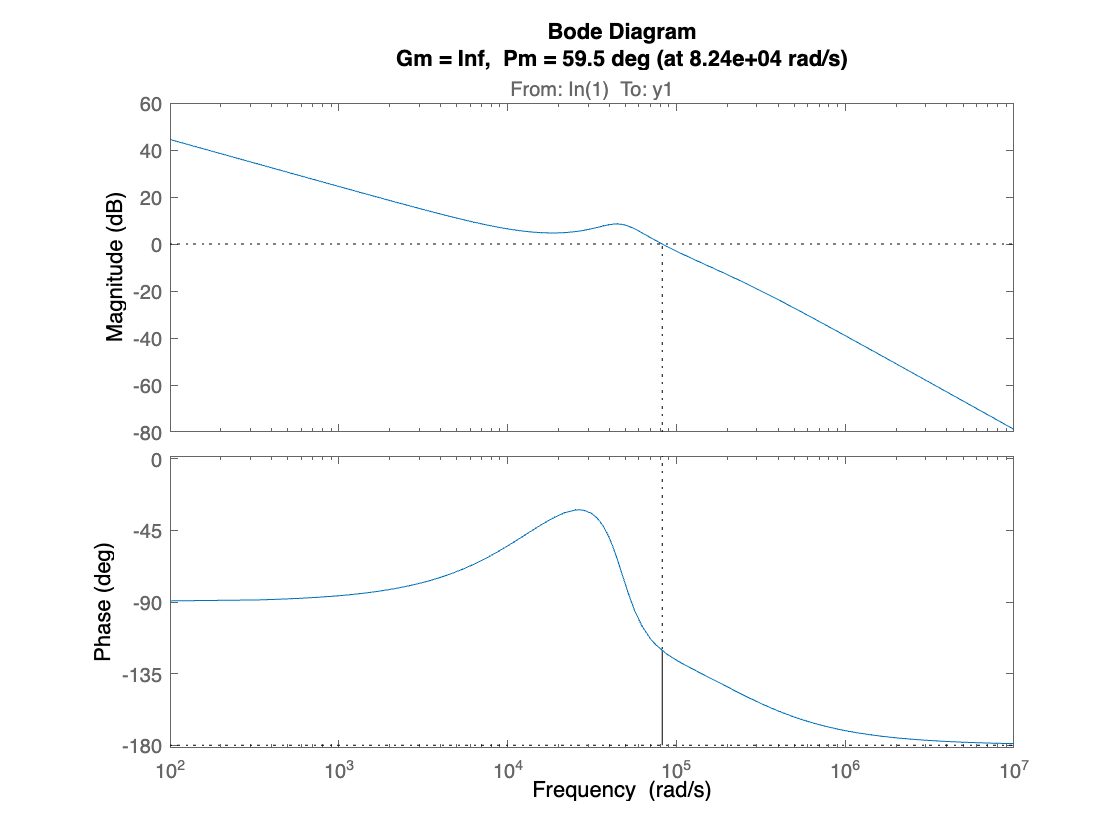

s=tf('s');
Cpid=minreal(Kp*(taui*s+1)/(taui*s)*(taud*s+1)/(alpha*taud*s+1));
Gol=minreal(G*Cpid);
Gcl=minreal(Gol/(1+Gol));
margin(Gol);

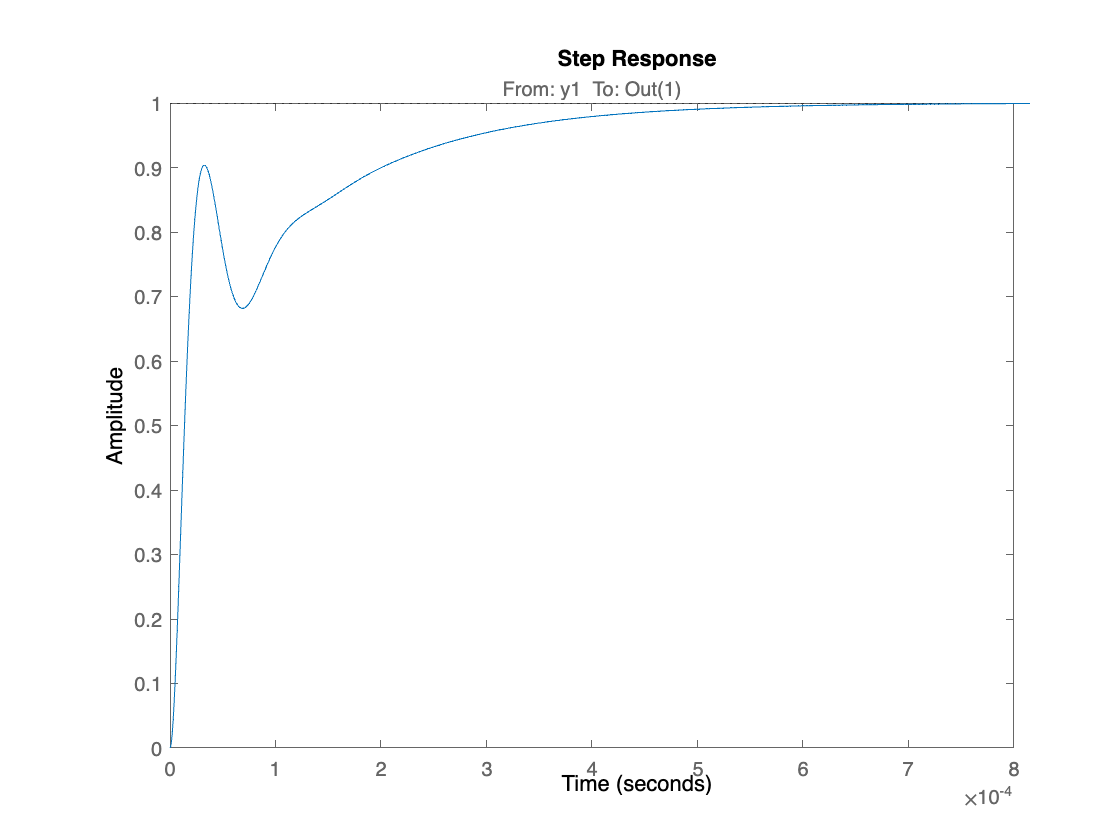

step(1*Gcl);

## Z-Transform and Output

format long
Gz=c2d(Cpid,1/10e3,'tustin');
Gz.Variable= 'z^-1'

Gz =
 
  0.4167 + 0.08307 z^-1 - 0.01194 z^-2
  ------------------------------------
     1 - 0.1959 z^-1 - 0.8041 z^-2
 
Sample time: 0.0001 seconds
Discrete-time transfer function.



[num, den] = tfdata(Gz, 'v');

format long
% Open the file for writing
fileID = fopen('../Code/Buck converter PWM/lib/Controllers/Data.h', 'w');

% Write the array declaration to the file
fprintf(fileID, 'double num[%d] = {',length(num));

% Write each element of the array to the file
for i = 1:length(num)
    fprintf(fileID, '%0.16f', num(i));
    
    % Add a comma after each element except the last one
    if i < length(num)
        fprintf(fileID, ', ');
    end
end

% Complete the array declaration
fprintf(fileID, '};\n');

% Write the array declaration to the file
fprintf(fileID, 'double den[%d] = {',length(den));

% Write each element of the array to the file
for i = 1:length(num)
    fprintf(fileID, '%0.16f', den(i));
    
    % Add a comma after each element except the last one
    if i < length(den)
        fprintf(fileID, ', ');
    end
end

% Complete the array declaration
fprintf(fileID, '};\n');

% Close the file
fclose(fileID);

